x = importdata("jumpcrackWu.txt");
xcum = cumsum(x,2);
z = zeros(30,1);
data = [z,xcum]

data =          0    0.6000    1.0200    1.4400    1.8900    2.4500    3.0500    3.7300
         0    0.7800    1.2000    1.8100    2.3700    3.0000    3.8400    4.7300
         0    1.2500    2.1600    3.0300    3.7400    4.8000    6.0900    7.8300
         0    1.1400    1.9400    2.7800    3.7100    4.6600    6.1000    8.0500
         0    1.1900    1.7700    2.5800    3.3200    4.4600    5.5800    7.0500
         0    1.0100    1.6500    2.4100    3.2100    3.9600    5.1400    6.5300
         0    1.2800    1.8000    2.8400    3.6100    4.8300    6.3600    8.5300
         0    0.6300    0.9800    1.5400    1.9100    2.4000    2.9900    3.6700
         0    1.4600    2.1600    3.1200    4.3400    5.5000    7.3300    9.9300
         0    0.7300    1.0300    1.4100    1.7100    2.3000    2.8800    3.5100


avedata = mean(data)

avedata =          0    0.9620    1.5300    2.2037    2.8943    3.7427    4.8067    6.2063


%crackdata1のインポート
crack1jump = importdata("dataset/jumpcrackWu.txt");

crack1jump =     0.6000    0.4200    0.4200    0.4500    0.5600    0.6000    0.6800
    0.7800    0.4200    0.6100    0.5600    0.6300    0.8400    0.8900
    1.2500    0.9100    0.8700    0.7100    1.0600    1.2900    1.7400
    1.1400    0.8000    0.8400    0.9300    0.9500    1.4400    1.9500
    1.1900    0.5800    0.8100    0.7400    1.1400    1.1200    1.4700
    1.0100    0.6400    0.7600    0.8000    0.7500    1.1800    1.3900
    1.2800    0.5200    1.0400    0.7700    1.2200    1.5300    2.1700
    0.6300    0.3500    0.5600    0.3700    0.4900    0.5900    0.6800
    1.4600    0.7000    0.9600    1.2200    1.1600    1.8300    2.6000
    0.7300    0.3000    0.3800    0.3000    0.5900    0.5800    0.6300


%全サンプルのプロット
z = transpose(zeros(1,30));
crack1time = [0 10000:5000:40000];
crack1cum = cumsum([z crack1jump],2);
%増分のグラフ
crack1mulist = zeros (1,7);
crack1lambdalist = zeros (1,7);
for i=1:7
crack1mlelist = mle(crack1jump(:,i) ,'distribution','InverseGaussian');
crack1mulist (i) = crack1mlelist (1);
crack1lambdalist (i) = crack1mlelist (2) ;
end
crack1interval = 1:1:7;
crack1cummulist = cumsum([0 crack1mulist])

crack1cummulist =          0    0.9620    1.5300    2.2037    2.8943    3.7427    4.8067    6.2063


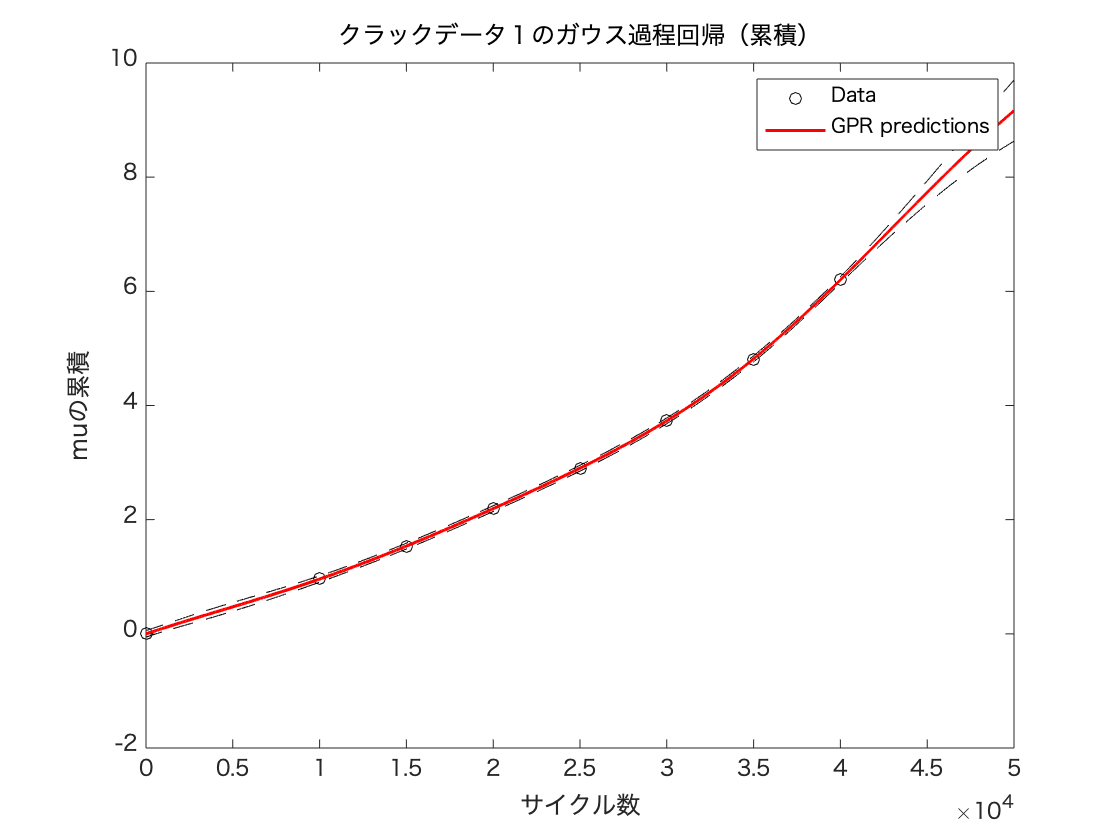

gprMdl = fitrgp(transpose(crack1time),transpose(crack1cummulist),'Basis','linear',...
      'FitMethod','exact','PredictMethod','exact');
%ypred = resubPredict(gprMdl);
x = linspace(0,50000,50000)';
[ypred,~,yci] = predict(gprMdl,x);
plot(crack1time',crack1cummulist.','ko');
hold on;
plot(x,ypred.','r','LineWidth',1.5);
plot(x,yci(:,1),'k--');
plot(x,yci(:,2),'k--');
xlabel('サイクル数');
ylabel('muの累積');
title('クラックデータ１のガウス過程回帰（累積）');
legend('Data','GPR predictions');
hold off

predict(gprMdl,crack1time.').'

ans =    -0.0007    0.9600    1.5384    2.1934    2.9021    3.7334    4.8186    6.2004


crack1cummulist

crack1cummulist =          0    0.9620    1.5300    2.2037    2.8943    3.7427    4.8067    6.2063


gprMdl = fitrgp(transpose(crack1interval),transpose(crack1mulist),'Basis','linear',...
      'FitMethod','exact','PredictMethod','exact')

gprMdl =   RegressionGP
             ResponseName: 'Y'
    CategoricalPredictors: []
        ResponseTransform: 'none'
          NumObservations: 7
           KernelFunction: 'SquaredExponential'
        KernelInformation: [1×1 struct]
            BasisFunction: 'Linear'
                     Beta: [2×1 double]
                    Sigma: 0.1275
        PredictorLocation: []
           PredictorScale: []
                    Alpha: [7×1 double]
         ActiveSetVectors: [7×1 double]
            PredictMethod: 'Exact'
            ActiveSetSize: 7
                FitMethod: 'Exact'
          ActiveSetMethod: 'Random'
        IsActiveSetVector: [7×1 logical]
            LogLikelihood: 1.6052
         ActiveSetHistory: []
           BCDInformation: []


  Properties, Methods


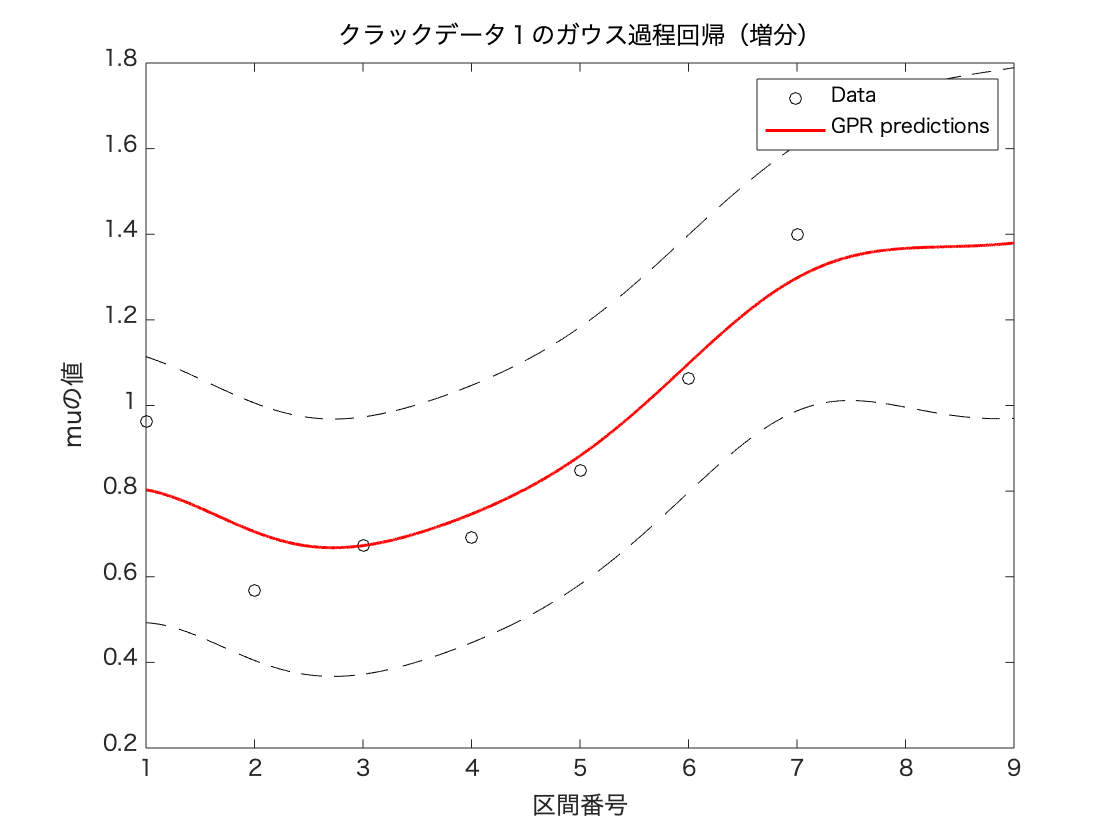

%ypred = resubPredict(gprMdl);
x = linspace(1,9,10000)';
[ypred,~,yci] = predict(gprMdl,x);
plot(crack1interval',crack1mulist.','ko');
hold on;
plot(x,ypred.','r','LineWidth',1.5);
plot(x,yci(:,1),'k--');
plot(x,yci(:,2),'k--');
xlabel('区間番号');
ylabel('muの値');
title('クラックデータ１のガウス過程回帰（増分）');
legend('Data','GPR predictions');
hold off

# クラックデータ２のGP

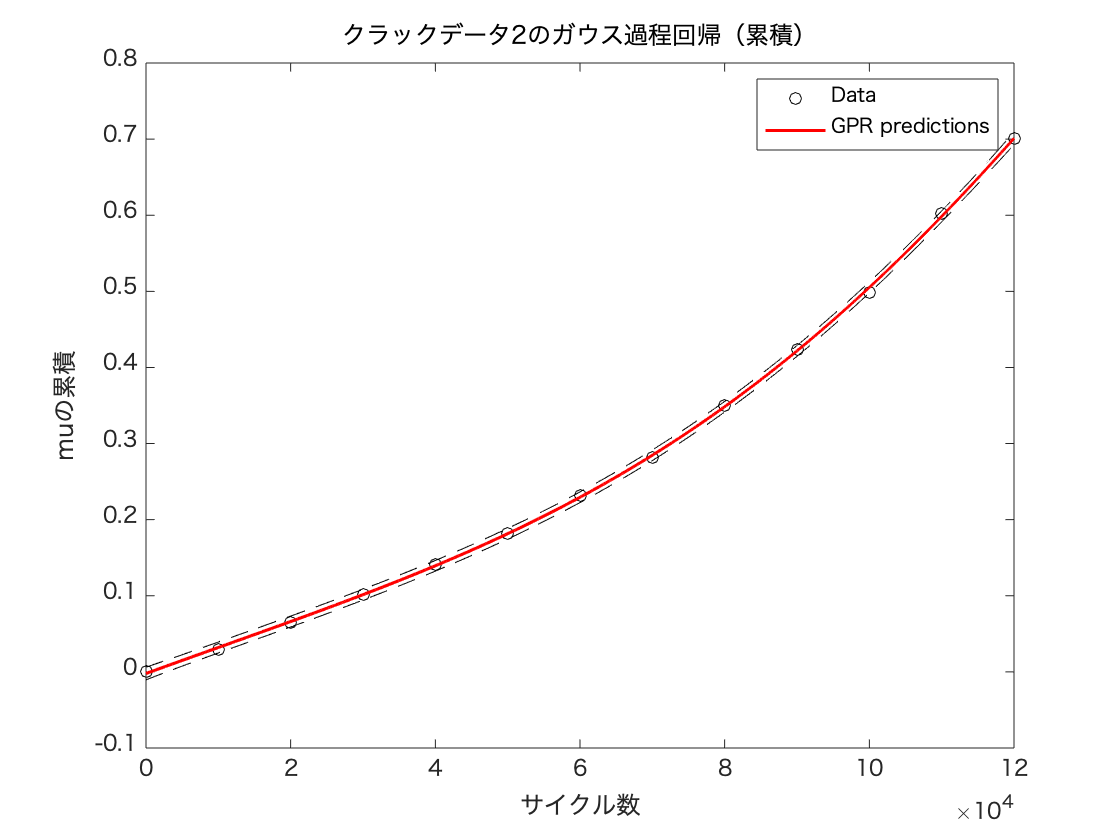

%crack2累積GP
gprMdl = fitrgp(transpose(crack2time),transpose(crack2cummulist),'Basis','linear',...
      'FitMethod','exact','PredictMethod','exact');
%ypred = resubPredict(gprMdl);
x = linspace(0,120000,120000)';
[ypred,~,yci] = predict(gprMdl,x);
plot(crack2time',crack2cummulist.','ko');
hold on;
plot(x,ypred.','r','LineWidth',1.5);
plot(x,yci(:,1),'k--');
plot(x,yci(:,2),'k--');
xlabel('サイクル数');
ylabel('muの累積');
title('クラックデータ2のガウス過程回帰（累積）');
legend('Data','GPR predictions');
hold off

predict(gprMdl,crack2time.').'

ans =    -0.0021    0.0321    0.0662    0.1015    0.1394    0.1816    0.2295    0.2847    0.3485    0.4218    0.5051    0.5985    0.7011


crack2cummulist

crack2cummulist =          0    0.0295    0.0652    0.1014    0.1405    0.1824    0.2314    0.2814    0.3500    0.4238    0.4988    0.6020    0.7012


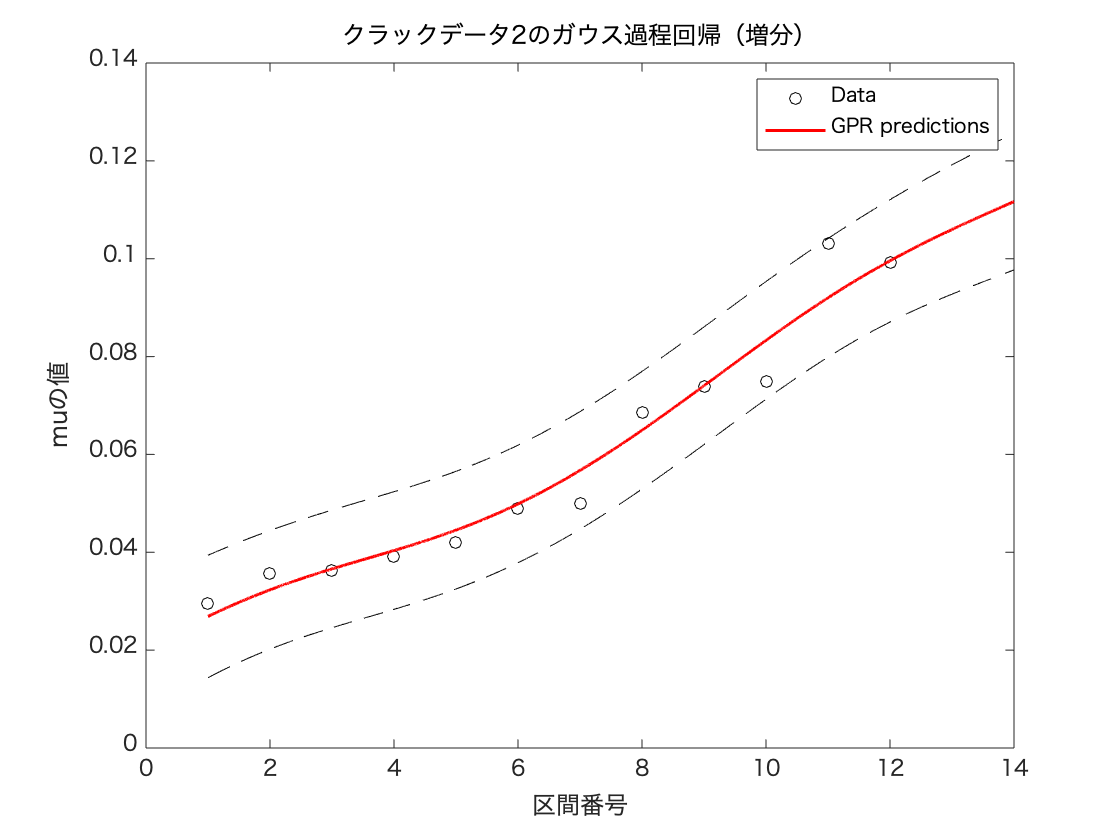

%crack2増分GP
gprMdl = fitrgp(transpose(crack2interval),transpose(crack2mulist),'Basis','linear',...
      'FitMethod','exact','PredictMethod','exact');
x = linspace(1,14,10000)';
[ypred,~,yci] = predict(gprMdl,x);
plot(crack2interval',crack2mulist.','ko');
hold on;
plot(x,ypred.','r','LineWidth',1.5);
plot(x,yci(:,1),'k--');
plot(x,yci(:,2),'k--');
xlabel('区間番号');
ylabel('muの値');
title('クラックデータ2のガウス過程回帰（増分）');
legend('Data','GPR predictions');
hold off

predict(gprMdl,crack2interval.').'

ans =     0.0269    0.0323    0.0366    0.0404    0.0445    0.0499    0.0567    0.0649    0.0740    0.0833    0.0920    0.0996


crack2mulist

crack2mulist =     0.0295    0.0357    0.0362    0.0390    0.0419    0.0490    0.0500    0.0686    0.0738    0.0750    0.1032    0.0992


# クラックデータ3のGP

%crack3累積GP
gprMdl = fitrgp(transpose(crack3time),transpose(crack3cummulist),'Basis','linear',...
      'FitMethod','exact','PredictMethod','exact');

関数または変数 'crack3time' が認識されません。

%ypred = resubPredict(gprMdl);
x = linspace(0,120000,90000)';
[ypred,~,yci] = predict(gprMdl,x);
plot(crack3time',crack3cummulist.','ko');
hold on;
plot(x,ypred.','r','LineWidth',1.5);
plot(x,yci(:,1),'k--');
plot(x,yci(:,2),'k--');
xlabel('サイクル数');
ylabel('muの累積');
title('クラックデータ3のガウス過程回帰（累積）');
legend('Data','GPR predictions');
hold off
predict(gprMdl,crack3time.').'
crack3cummulist

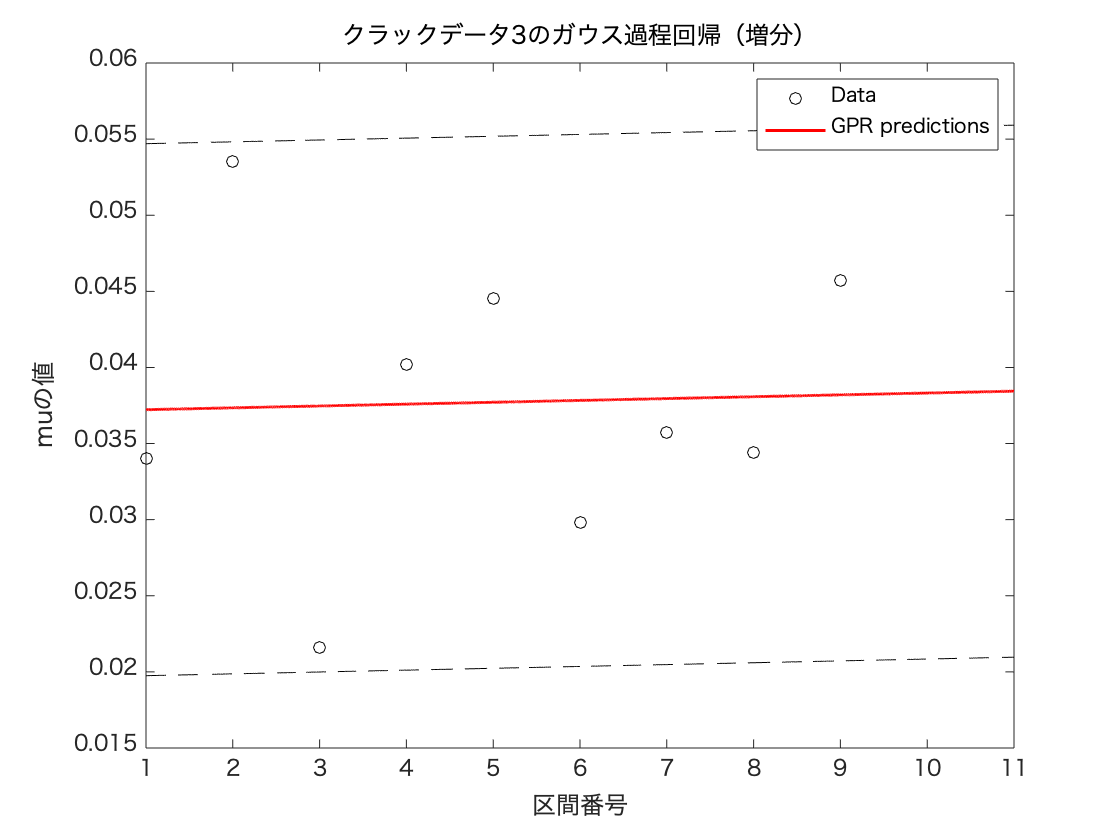

%crack2増分GP
gprMdl = fitrgp(transpose(crack3interval),transpose(crack3mulist),'Basis','linear',...
      'FitMethod','exact','PredictMethod','exact');
x = linspace(1,11,10000)';
[ypred,~,yci] = predict(gprMdl,x);
plot(crack3interval',crack3mulist.','ko');
hold on;
plot(x,ypred.','r','LineWidth',1.5);
plot(x,yci(:,1),'k--');
plot(x,yci(:,2),'k--');
xlabel('区間番号');
ylabel('muの値');
title('クラックデータ3のガウス過程回帰（増分）');
legend('Data','GPR predictions');
hold off